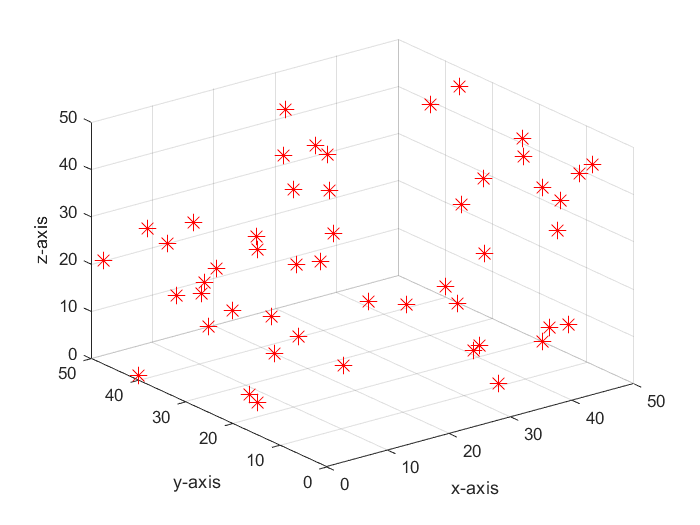

clear
clc
syms x y z t
m=csvread('coord.csv');
dose=csvread('r.csv');
xi=m(:,1);
yi=m(:,2);
zi=m(:,3);
zi=double(zi);

plot3(xi,yi,zi,'*r','MarkerSize',10);
axis([0 50 0 50 0 50]);
xlabel('x-axis');
ylabel('y-axis');
zlabel('z-axis');
grid on
hold on

% to plot the source
%x=0*t;
%y=0*t;
%z=t;
%fplot3x,y,z,[0 10],'g','LineWidth',5)
% to obtain distance (radius of every cylinder)
%r=sqrt(xi.^2+yi.^2);
x=t;
y=t;
z=t;
%r=sqrt((x))


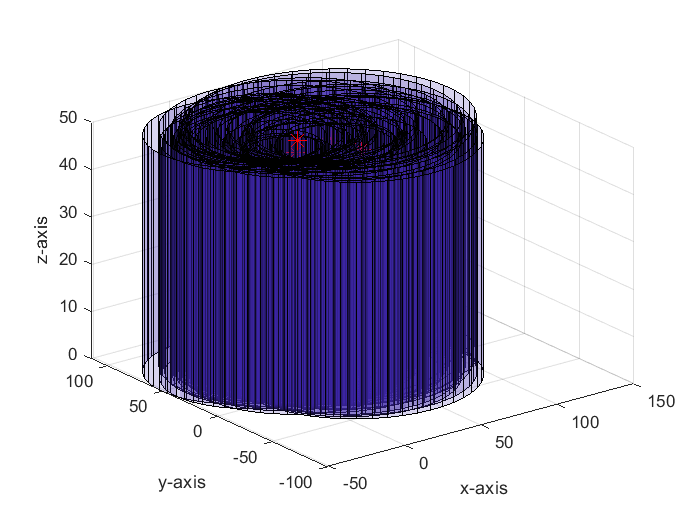

for i=1:50
    [X,Y,Z]=cylinder2P(dose(i),50,[xi(i),yi(i),0],[xi(i),yi(i),50]);
    surf(X,Y,Z)
    alpha 0.2
end
hold off
axis auto